# Stabilität

Sei $I_\delta:=[\delta,10\,\delta]$, mit $0 <\delta \leq 10^{-2}$, und 


$$$$ f(x)=\frac{\sin^2(x)}{x^2}, \qquad g(x)=\frac{1-\cos^2(x)}{x^2}, \quad x \in I_\delta.$$$$


Die Funktion $f$ ist auf $I_\delta$ gut konditioniert, und $f(x)=g(x)$, $0 \leq f(x)\leq 1$ für alle $x \in I_\delta$.

Wir wählen  Werte der Form $\delta=10^{-k}$, $k=2,3,\ldots$:

k=4;

Die beiden Funktionen $f$ und $g$ werden  in MATLAB ausgewertet und geplottet.

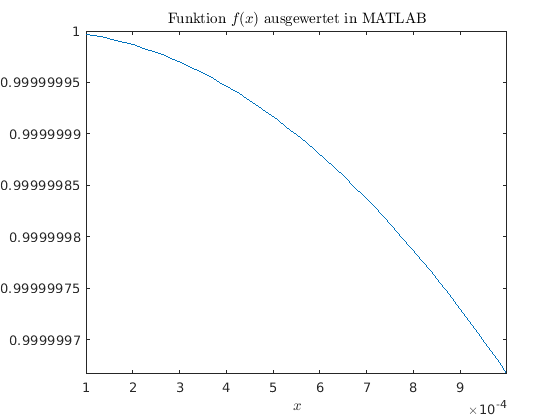

 plotf(k);

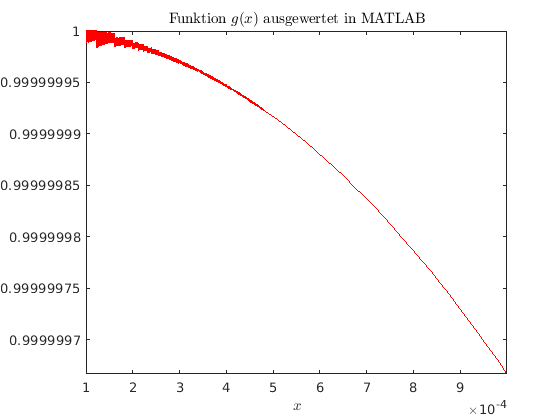

 plotg(k);

#  Aktivität:

Variieren Sie $k$ und erklären Sie die Resultate. 

function plotf(k)
delta=10^(-k);
delta10=10*delta;
fplot(@(x) (sin(x).^2)./(x.^2),[delta,delta10]);
title('Funktion $f(x)$ ausgewertet in MATLAB','Interpreter','latex');
xlabel('$x$','Interpreter','latex');
hold off;
end

function plotg(k)
delta=10^(-k);
delta10=10*delta;
fplot(@(x) (1-cos(x).^2)./(x.^2), [delta,delta10],'r');
title('Funktion $g(x)$ ausgewertet in MATLAB','Interpreter','latex');
xlabel('$x$','Interpreter','latex');
hold off;
end